Constants

T_outside = -3; % celsius
h_window = 1.4; % W/m^2-K
k_wall = .04; % W/m-K
D_tile = 3000; % kg/m^3
c_tile = 800; % J/kg-K

h_indoors = 15; % W/m^2-K
h_outdoors = 30; % W/m^2-K

A_window = 8; % m^2

A_floor = 5 * 5; % m^2

H_house = 3; % m
W_house = 5; % m
L_wall = .07; % m
L_tile = .25; % m

A_hi = 2 * A_floor + 4 * W_house * H_house - A_window

A_hi = 102

A_ho = (5 + 2 * L_wall) * (2 * (5 + 2 * L_wall) + ...
    4 * (3 + 2 * L_wall) + ...
    2 * .9 + L_wall) - A_window

A_ho = 119.0094


A_cs = 2 * (5 + 2 * L_wall) ^ 2 + ...
    4 * (3 + 2 * L_wall) * (5 + 2 * L_wall) + ...
    .9 * (5 + 2 * L_wall) - A_window

A_cs = 114.0236


V_tile = A_floor * L_tile;
m_tile = V_tile * D_tile;

More Things

q = @(t) -361 * cos(pi * t / (12 * 3600)) + ...
    224 * cos(pi * t / (6 * 3600)) + 210;

R_window = 1 / (h_indoors * A_window) + ...
    1 / (h_window * A_window) + ...
    1 / (h_outdoors * A_window);

R_flair = 1 / (h_indoors * 2 * (A_floor + 2 * L_tile * 5));

R_wall = 1 / (h_indoors * A_hi) + ...
    1 / (h_outdoors * A_ho) + ...
    L_wall / (k_wall * A_cs);

R_tot = 1 / (1 / R_window + 1 / R_wall) + R_flair

R_tot = 0.0152


C_tile = m_tile * c_tile;

the ode????

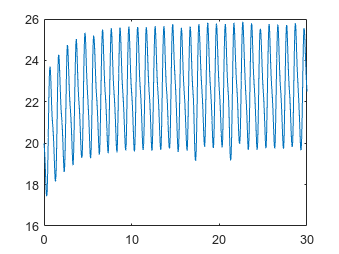

dT = @(t, T) -(T - T_outside) / (R_tot * C_tile) + (q(t) * A_window) / C_tile;

[t, T] = ode45(dT, 0:(3600 * 24 * 30), 20);

clf;
plot(t / (24 * 3600), T);

the air??? 

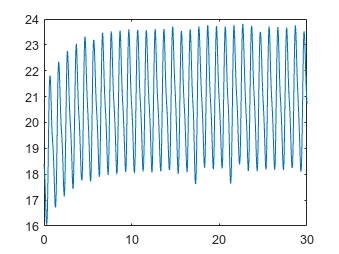

T_air = T * (1 / ((1 / R_wall) + (1 / R_window))) / (R_tot);

plot(t / (3600 * 24), T_air)